% Take an image as input and 
% output small images of each dot

% clear
clc
close all

% param
cproxpixel = 30; % # of pixels near each centre looked at to count proximal centres
% univsens = 0.45; % universal sensitivity to make binary image
storeImgEachDot = true;
storeInPredictionFolder = true;
browseImgDirectory = true;

% get input_image path and filename
if browseImgDirectory
    [filename, pathname] = uigetfile(...    
    {'*.jpg; *.JPG; *.jpeg; *.JPEG; *.img; *.IMG; *.tif; *.TIF; *.tiff, *.TIFF','Supported Files (*.jpg,*.img,*.tiff,)'; ...
    '*.jpg','jpg Files (*.jpg)';...
    '*.JPG','JPG Files (*.JPG)';...
    '*.jpeg','jpeg Files (*.jpeg)';...
    '*.JPEG','JPEG Files (*.JPEG)';...
    '*.img','img Files (*.img)';...
    '*.IMG','IMG Files (*.IMG)';...
    '*.tif','tif Files (*.tif)';...
    '*.TIF','TIF Files (*.TIF)';...
    '*.tiff','tiff Files (*.tiff)';...
    '*.TIFF','TIFF Files (*.TIFF)'},...    
    'MultiSelect', 'on');
    input_img = strcat(pathname,filename);
else
    input_img = '2020-09-25_mgLAMP with Quasr-BIP12nt_TritonX100_5_gel_.lif_40min_NTC_2_ch00.tif';% Specify the filename here
end

input_img = 'C:\Users\alano\mgLAMPImageProcessing\20200930-5.0_6_6.7-1_ch00.tif'


% proxbound = 20; % number of pixels around each centre to look for other signals, deprecated
%read tif file into a monochromatic array
A = imread(input_img);
% sens_array = [0.52 0.48 0.50 0.49 0.53 0.51 0.51 0.51 0.51];%adjust sensiticity one by one subimage, mainly the 5th
sens_array = [0.30 0.30 0.25 0.35 0.42 0.30 0.25 0.23 0.23];%universal regional sens
% sens_array = univsens*ones(9,1); %universal sensitivity
shape_area_threshold_array = [12 8 10 6 5 15 15 15 15];
% sens_array = [0.15 0.30 0.25 0.35 0.40 0.30 0.25 0.40 0.23];
% shape_area_threshold_array = [15 30 15 10 5 10 15 15 10];
%crop = [50 960 50 960]; % Adjust x1,x2,y1,y2 for cropping
crop = [0 size(A,2) 0 size(A,1)];
% crop = [0 size(A,1) 0 size(A,2)]
A_doub = A(:,:,2);
A_doub = imadjust(A_doub);

%crop bubbles
%A_crop = A_doub(crop(3):crop(4),crop(1):crop(2));
% A_crop = cropbubbles(A_doub);
A_crop = A_doub;

% %set cropping param and initialize counting matrices
A_sep = zeros(9,4);
A_sep(1,:)= [1,300,1,300];A_sep(2,:)= [1,300,301,600];A_sep(3,:)=[1,300,601,crop(4)-crop(3)];
A_sep(4,:)= [301,600,1,300];A_sep(5,:)=[301,600,301,600];A_sep(6,:)= [301,600,601,crop(4)-crop(3)];
A_sep(7,:)= [601,crop(2)-crop(1),1,300];A_sep(8,:)=[601,crop(2)-crop(1),301,600];
A_sep(9,:)= [601,crop(2)-crop(1),601,crop(4)-crop(3)];
counted = zeros(9,1);
centers_all = [];

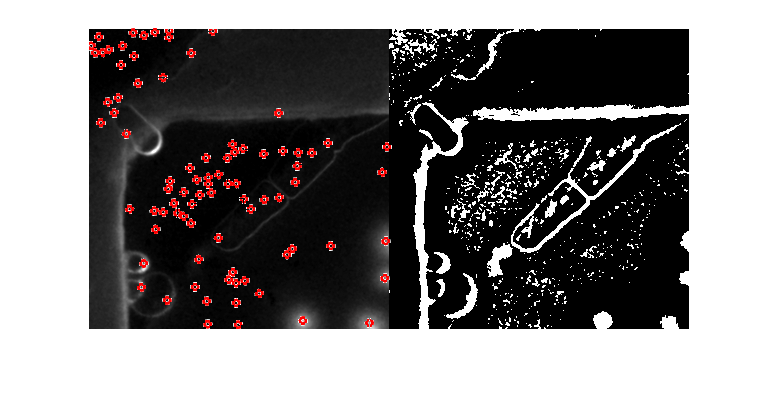

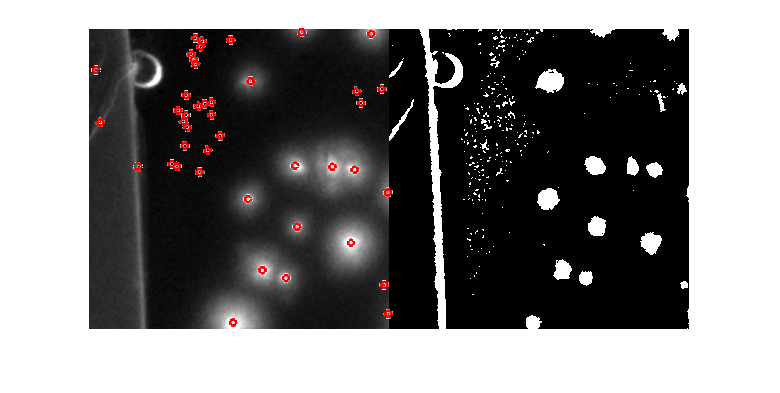

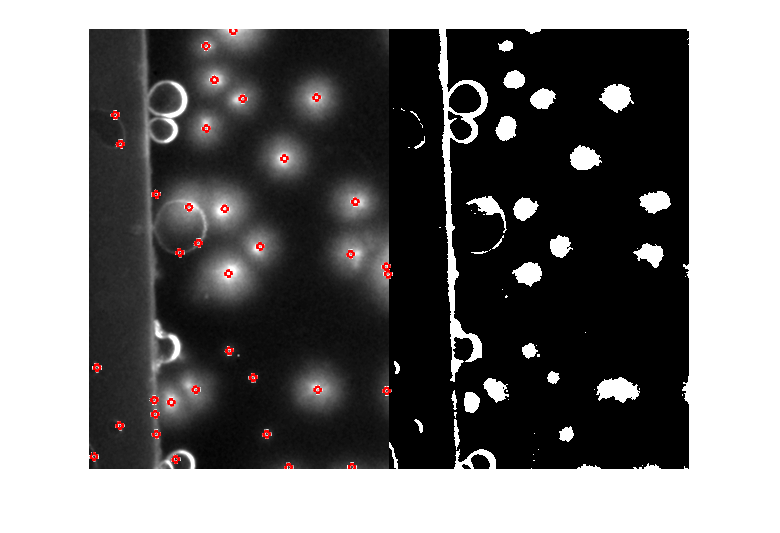

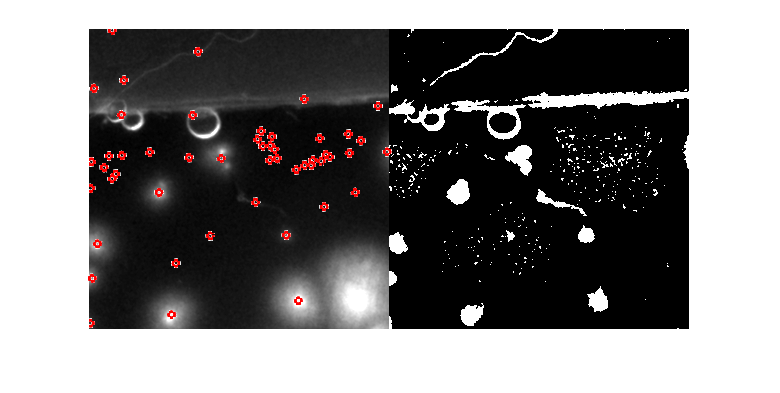

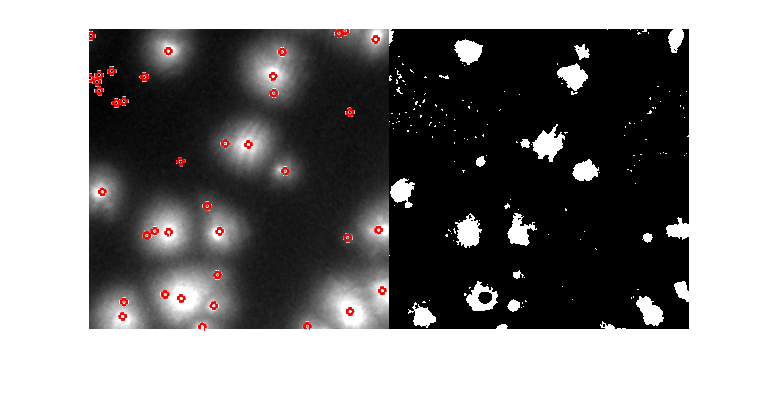

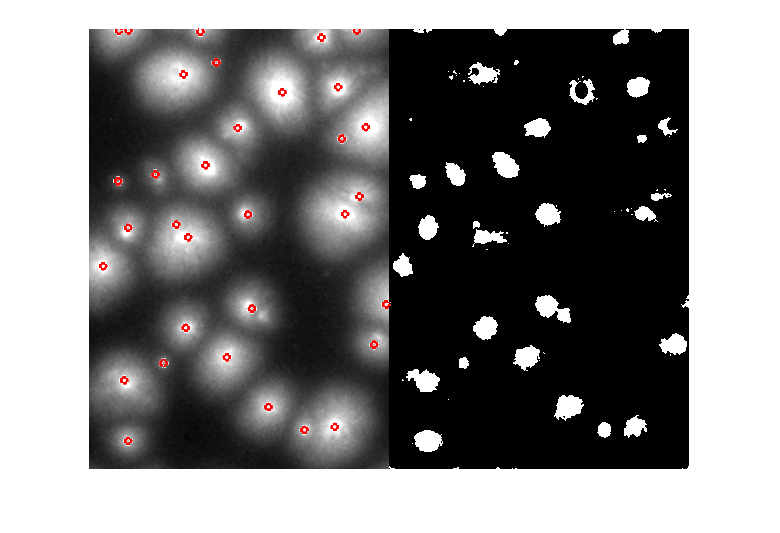

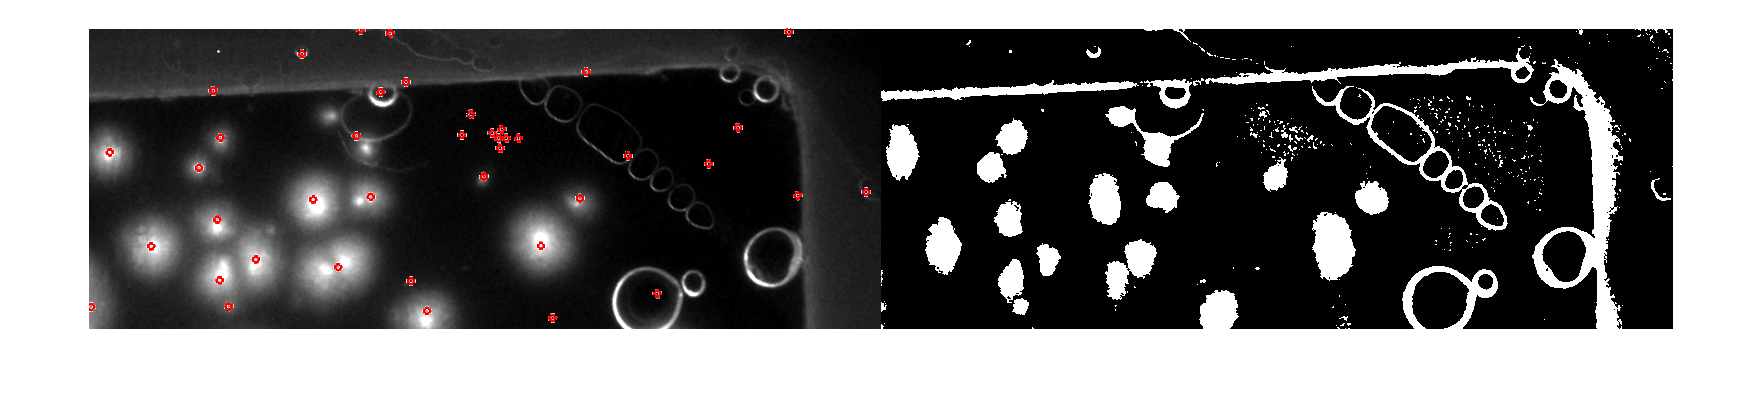

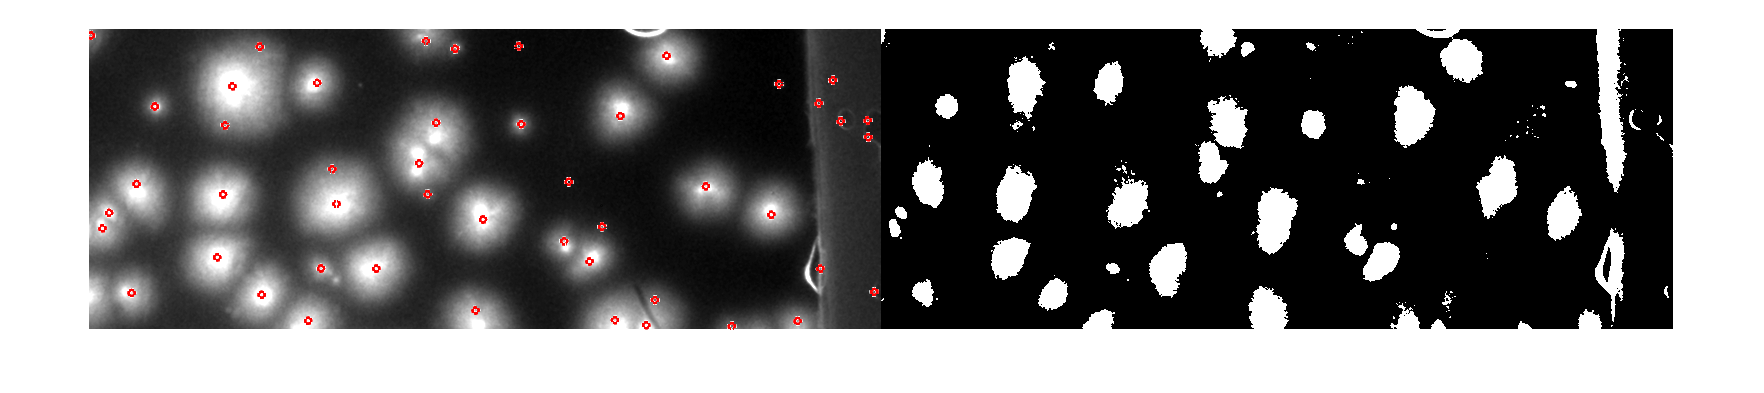

for i = 1:9
    %slice image into 9 pieces and make into binary from specificed
    %sensitvity
    binary_sensitivity = sens_array(i);
    shape_area_threshold = shape_area_threshold_array(i);
    A1 = A_crop(A_sep(i,3):A_sep(i,4),A_sep(i,1):A_sep(i,2));
    A2 = imbinarize(A1,'adaptive','Sensitivity',binary_sensitivity);    
    figure(i)
    imshowpair(A1, A2, 'montage')
    %imshow(A2)
    
    %find centres of bright dots
    cc = bwconncomp(A2,26);
    s = regionprops('table',cc,'Area','Centroid');
    idx = find([s.Area] > shape_area_threshold); 
    BW2 = ismember(labelmatrix(cc), idx);  
    ss  = regionprops('table',BW2,'Centroid');
    centers = ss.Centroid;
    
    %count bright dots and visualize them
    radii = 3*ones(size(centers,1),1);
    viscircles(centers,radii);
    %fn = "Counted_"+string(size(radii,1))+input_img+string(i);
    fn = 'collage'+string(i)'+'.jpg';
%     saveas(figure(i),fn);
    counted(i,1) = size(radii, 1);
    centers_all = [centers_all;(centers + [A_sep(i,1)-1,A_sep(i,3)-1])];
end


% extend orignal picture by 10 pixels to avoid NaN in next step
expand_each_side_by = cproxpixel;
A_doub_expanded = 256*ones(size(A_doub,1)+expand_each_side_by*2, ...
    size(A_doub,2)+expand_each_side_by*2);
A_doub_expanded(expand_each_side_by+1:expand_each_side_by+size(A_doub,1), ...
    expand_each_side_by+1:expand_each_side_by+size(A_doub,2)) = A_doub;
    
% get brightness of (proxbound*2+1)^2 dots with proxbound pixels of each centre
% A_doub is the original picture
% centers_all are the coordinates of all suspected centres
centers_all_rounded = round(centers_all);
% brightness_near_centers = zeros(size(centers_all_rounded,1),expand_each_side_by^2*4);
centers_all_rounded_expaneded = centers_all_rounded+cproxpixel;

% % find # of other centres near each centre, within cproxpixel
% % # stored in the 3rd column of centers_all_rounded
% % now centers_all_rounded has columns x-y-prox_centres
% for j = 1:size(centers_all_rounded,1)
%     x = centers_all_rounded(j,1);
%     y = centers_all_rounded(j,2);
%     centers_all_rounded(j,3) = -1; % not counting itself
%     for k = 1:size(centers_all_rounded,1)
%         if abs(x-centers_all_rounded(k,1)) <= cproxpixel & ...
%                 abs(y-centers_all_rounded(k,2)) <= cproxpixel
%             centers_all_rounded(j,3) = centers_all_rounded(j,3) + 1;
%         end
%     end
% end

% % get brightness of proximal 441 dots into centers_all_rounded
% for i = 1:size(centers_all_rounded,1) % row in centers_all_rounded
%     counter = 1;
%     for j = -proxbound:proxbound % x coord
%         for k = -proxbound:proxbound %y coord
%             centers_all_rounded(i,3+counter) = ...
%                 A_doub_expanded( ...
%                 centers_all_rounded(i,2)+k+expand_each_side_by ...
%                 , centers_all_rounded(i,1)+j+expand_each_side_by);
%             counter = counter + 1;
%         end
%     end
% end

% save cropped images centred around centers_all_rounded
if storeImgEachDot
    if storeInPredictionFolder
        fullDirectory = [pwd '/Prediction'];
        if isfolder(fullDirectory)
            rmdir(fullDirectory,'s');
        end
    else
        fullDirectory = [pwd '/' input_img '_imgEachDot'];
    end
    mkdir(fullDirectory);
    for i = 1:size(centers_all_rounded_expaneded,1)
        imgEachDot = imcrop(A_doub_expanded, ...
            [centers_all_rounded_expaneded(i,1)-cproxpixel ...
            centers_all_rounded_expaneded(i,2)-cproxpixel ...
            cproxpixel*2 cproxpixel*2]);
        thisFileName = sprintf('Dot #%5d.png', i);
        fullFileName = fullfile(fullDirectory, thisFileName);
        imwrite(uint8(imgEachDot), fullFileName);
    end
end


% % define training data
% centers_classification_T = [0 0 1];
% centers_classification = transpose(centers_classification_T);

% feed inputs to neural network, weed out false pos
% use also number of other signals in the nearest 10 pixels each direction
% classification of 0,1,2,0.5

% apply model in another tif, possibly through another m file


% show original tif with counted dots overlay
radii_all = 3*ones(size(centers_all,1),1);
sum(counted)

ans = 439

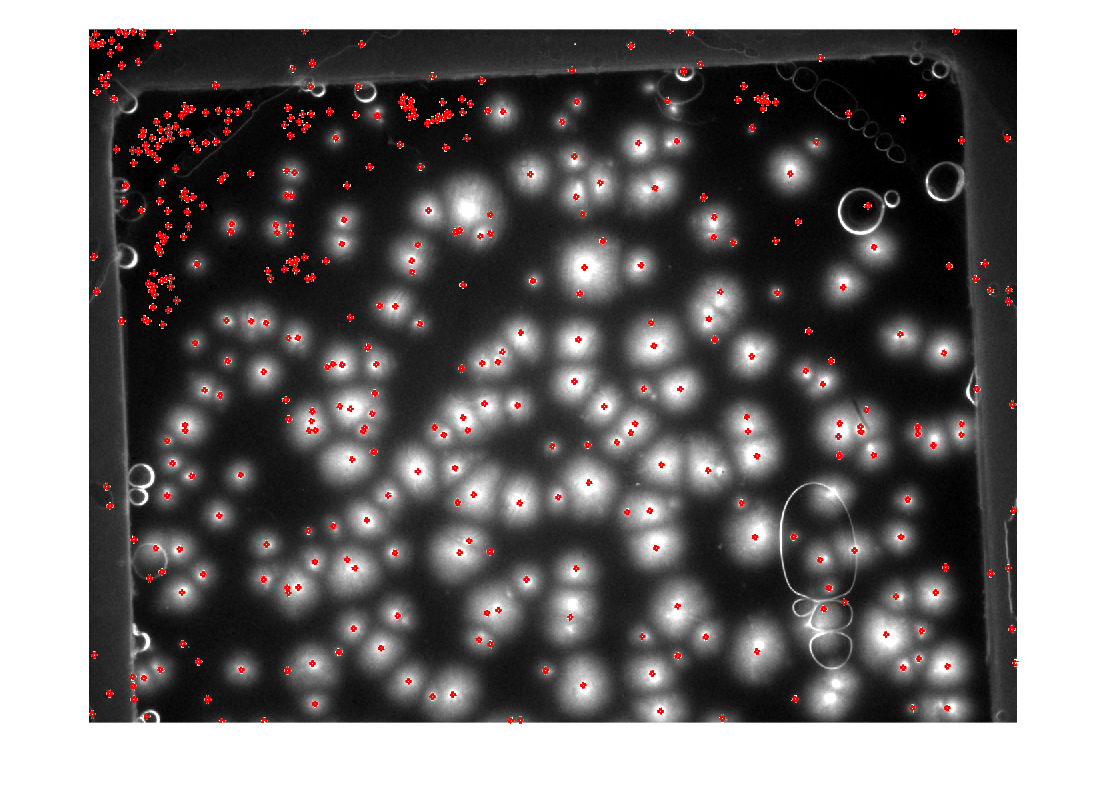

figure(10)
imshow(A_crop)
viscircles(centers_all,radii_all);